clear; close all; clc

## TO DO

% Handle NAN values
% Keep working on dataset

% Read Data
housing_data = readtable('housing.csv');

## Handle NAN values

% Set to median value of column

nan_columns = false(1,width(housing_data));

for col = 1:width(housing_data)
    if isnumeric(housing_data{:, col})  % Check if the column is numeric
        nan_columns(col) = any(isnan(housing_data{:, col}));
    end
end

nan_containing_columns = find(nan_columns);

if ~isempty(nan_containing_columns)
    fprintf('Columns containing NaN values: %s\n', num2str(nan_containing_columns));
else
    fprintf('No columns contain NaN values.\n');
end

Columns containing NaN values: 5



% Column 5 contains NaN values

nan_count = sum(isnan(housing_data{:,5}));
non_nan_count = sum(~isnan(housing_data{:,5}));
percentage = nan_count / size(housing_data, 1);
fprintf(['Nan amount in column 5', int2str(nan_count)]);

Nan amount in column 5207

disp(percentage);

    0.0100




column_5_median = median(housing_data{:,5},'omitnan');
column_5_mean = mean(housing_data{:,5},'omitnan');

disp(column_5_median);

   435




housing_data(isnan(housing_data{:, 5}), 5) = {column_5_median};

% Show nan count now
new_nan_count = sum(isnan(housing_data{:,5}));
disp(new_nan_count);

     0



% Store header values
treated_values_header = housing_data.Properties.VariableNames;

% Features
X = housing_data

X = 20640×10 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________

     -122.23      37.88              41                880              129             322           126          8.3252            4.526e+05          {'NEAR BAY'}  
     -122.22      37.86              21               7099             1106            2401          1138          8.3014            3.585e

%X = housing_data(:,[1:8,10:end]);

X = removevars(X,"ocean_proximity");
X = removevars(X,"median_house_value");
X_headers = X.Properties.VariableNames;
X = table2array(X);
% Labels
Y = housing_data(:,"median_house_value");
Y = table2array(Y);

% Dataset size
rows = size(housing_data, 1);
disp(rows);

       20640



% Randomize indicies
random_indicies = randperm(rows);

% Define calibration amount
calibration_split_point = 0.7;

% Row to split at
row_to_split_data_at = round(calibration_split_point * rows);

% Split into test and calibration units

X_calibration = X(random_indicies(1:row_to_split_data_at),:);
Y_calibration = Y(random_indicies(1:row_to_split_data_at),:);

X_test = X(random_indicies(row_to_split_data_at + 1:end),:);
Y_test = Y(random_indicies(row_to_split_data_at + 1:end),:);

% Mean and std of calibration data

X_calibration_mean = mean(X_calibration,1);
Y_calibration_mean = mean(Y_calibration);

X_calibration_std = std(X_calibration);
Y_calibration_std = std(Y_calibration);


% Zscore the calibration data
z_X_calibration = normalize(X_calibration,"zscore","std");
%z_Y_calibration(Y_calibration);
z_Y_calibration = normalize(Y_calibration,"zscore","std");



% Normalize and center test data using the calibration dataset
X_test_standardized = (X_test - X_calibration_mean) ./ X_calibration_std;
Y_test_standardized = (Y_test - Y_calibration_mean) ./ Y_calibration_std;


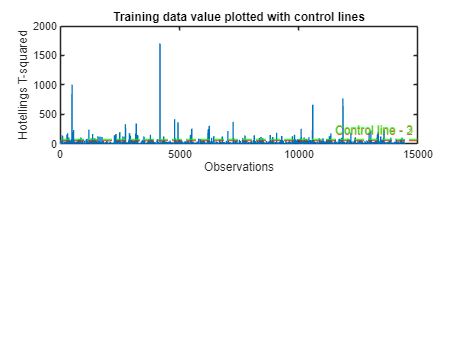

% Outlier visualization
[coeff_a, score_a, latent_a, tsquared_a, explained_a, mu_a] = pca(z_X_calibration, 'Economy',false);

% T2 -plot

% Mean and std
mean_t2 = mean(tsquared_a);
std_t2 = std(tsquared_a);
t2_control_at_2 = mean_t2 + 2 * std_t2;
t2_control_at_3 = mean_t2 + 3 * std_t2;
% Training data plot 
figure;
hold on;
subplot(2,1,1);
plot(tsquared_a);
xlabel('Observations');
ylabel('Hotellings T-squared');
hold on;
yline(t2_control_at_2,'--r', 'Control line - 2');
yline(t2_control_at_3,'--g', 'Control line - 3');
title('Training data value plotted with control lines');

alpha = 0.05; % Significance level
threshold = chi2inv(1 - alpha, size(score_a, 2))

threshold = 15.5073

display(threshold);

threshold = 15.5073

outliers = tsquared_a > threshold;
disp(sum(outliers));

        1124



% Find outliers
outlier_indices = find(outliers);

% Remove outliers from the normalized control data
z_X_calibration= z_X_calibration(~outliers, :); 
z_Y_calibration= z_Y_calibration(~outliers, :); 

X_calibration_mean_standard = mean(z_X_calibration,1);
Y_calibration_mean_standard = mean(z_Y_calibration);

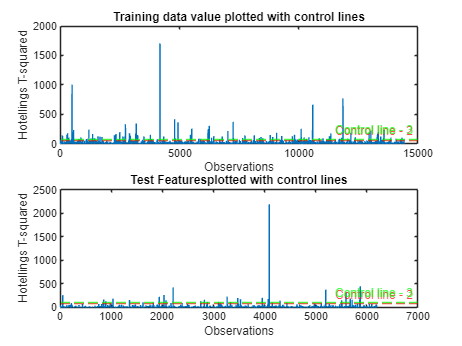

% Clean up test data
% Outlier visualization
[coeff_b, score_b, latent_b, tsquared_b, explained_b, mu_a] = pca(X_test_standardized, 'Economy',false);

% T2 -plot

% Mean and std
mean_t2 = mean(tsquared_b);
std_t2 = std(tsquared_b);
t2_control_at_2 = mean_t2 + 2 * std_t2;
t2_control_at_3 = mean_t2 + 3 * std_t2;


% Test data plot
subplot(2,1,2)
plot(tsquared_b);
xlabel('Observations');
ylabel('Hotellings T-squared');
hold on;
yline(t2_control_at_2,'--r', 'Control line - 2');
yline(t2_control_at_3,'--g', 'Control line - 3');
title('Test Featuresplotted with control lines');
hold off;

threshold_b = chi2inv(1 - alpha, size(score_b, 2))

threshold_b = 15.5073

display(threshold_b);

threshold_b = 15.5073

outliers_b = tsquared_b > threshold_b;
disp(sum(outliers_b));

   442



% Find outliers
outlier_indices = find(outliers_b);

% Remove outliers from normalized test data
X_test_standardized= X_test_standardized(~outliers_b, :); 
Y_test_standardized= Y_test_standardized(~outliers_b, :); 

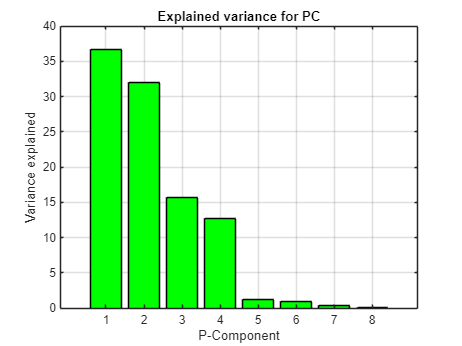

% Visualize component amount to make a decision
[coeff, score, latent, tsquared, explained, mu] = pca(z_X_calibration, 'Economy',false);

[Y_train_std, mu_y, sigma_y] = zscore(z_Y_calibration);

% Explained variance by PC
figure;
bar(explained, 'g');
xlabel('P-Component');
ylabel('Variance explained');
title('Explained variance for PC');
grid on;

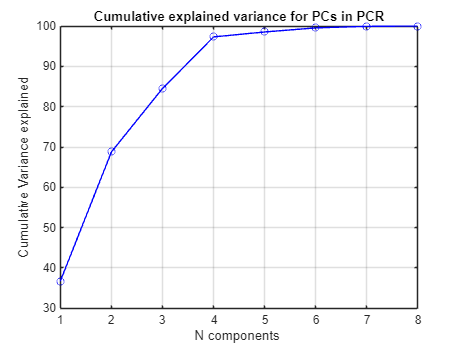

% Cumulative explained variance
% Cumulative variance - Plotted to see total explanation of combination of
% PC's
cumulative_variance = cumsum(explained);
plot(cumulative_variance,'-bo');
xlabel('N components ');
ylabel('Cumulative Variance explained');
title('Cumulative explained variance for PCs in PCR');
grid on;

## PLS model


% CV is the cross validation and 5 is the amount of K-folds
% Fit model using the pc amount from the pca analysis 

[XL,YL,XS,YS,BETA,PCTVAR,MSE,stats]= plsregress(z_X_calibration, z_Y_calibration, 8,'cv',5);

yfit_PLS_calibration = [ones(size(z_X_calibration,1),1) z_X_calibration]*BETA;

yfit_PLS_test = [ones(size(X_test_standardized,1),1) X_test_standardized]*BETA;

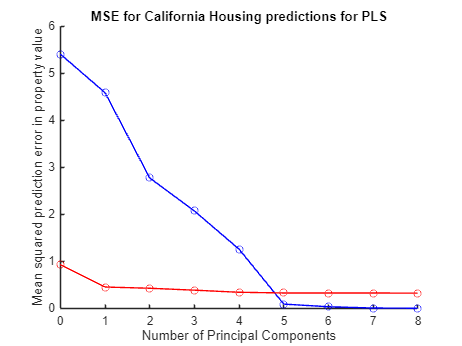

% PLS MSE Plot
% MSE FLoors after 2-4 principal components
figure;
hold on;
plot(0:8,MSE(1,:) ,'b-o');
plot(0:8,MSE(2,:), 'r-o');
xlabel('Number of Principal Components');
ylabel('Mean squared prediction error in property value');
title('MSE for California Housing predictions for PLS');
hold off;

% Rsquared - PLS - calibration
TSS = sum(z_Y_calibration.^2);
RSSPLS = sum((z_Y_calibration - yfit_PLS_calibration).^2);
r_squared_PLS = 1 - RSSPLS/TSS;
disp(['PLS calibration Q2: ',num2str(r_squared_PLS)]);

PLS calibration Q2: 0.65315


% Rsquared - PLS - test
TSS = sum(Y_test_standardized.^2);
RSSPLS = sum((Y_test_standardized - yfit_PLS_test).^2);
r_squared_PLS_test = 1 - RSSPLS/TSS;
disp(['PLS test Q2: ',num2str(r_squared_PLS_test)]);

PLS test Q2: 0.65625


% Q2 work for PLS calibration
Y_pred_in = yfit_PLS_calibration;
Y_true_in = z_Y_calibration;
Q2_in = 1 - sum((Y_true_in - Y_pred_in).^2) / sum((Y_true_in - mean(Y_true_in)).^2);
disp(['Q-squared for the initial calibration PLS: ', num2str(Q2_in)]);

Q-squared for the initial calibration PLS: 0.6528


if Q2_in > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Good prediction


% Q2 work for PLS test
Y_pred_in_test = yfit_PLS_test;
Y_true_in_test = Y_test_standardized;

Q2_in_test = 1 - sum((Y_true_in_test - Y_pred_in_test).^2) / sum((Y_true_in_test - mean(Y_true_in_test)).^2);

disp(['Q-squared for the initial test PLS: ', num2str(Q2_in_test)]);

Q-squared for the initial test PLS: 0.65565


if Q2_in_test > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Good prediction


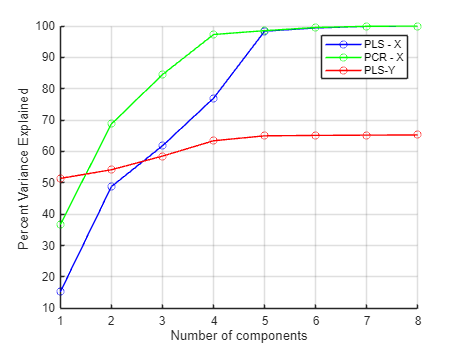

% PLS and PCR explained variance single plot for X
% Y Explained variance for PLS is not reaching any significant point with
% current variables
% X-explained seems to reach required levels for PCR with three components
% X-explained seems to reach required levels for PLS with four components
figure;
hold on;
plot(1:8,cumsum(100*PCTVAR(1,:)),'-bo', 'DisplayName','PLS - X');
plot(1:8,cumulative_variance,'-go', 'DisplayName','PCR - X');
plot(1:8,cumsum(100*PCTVAR(2,:)),'-ro', 'DisplayName','PLS-Y');
xlabel('Number of components');
ylabel('Percent Variance Explained ');
grid on;
legend show;
hold off;

## PCR Regression

beta_PCR = regress(z_Y_calibration, score(:,1:4));

% Transform B's from PC's
beta_PCR = coeff(:,1:4)*beta_PCR;
intercept = Y_calibration_mean - X_calibration_mean * beta_PCR;
%Step 3
beta_PCR = [intercept; beta_PCR];

% Project onto test set

%Add first columns of ones
yfit_PCR_calibration = [ones(size(z_X_calibration,1),1) z_X_calibration]*beta_PCR;


yfit_PCR_test = [ones(size(X_test_standardized,1),1) X_test_standardized]*beta_PCR;


% R-squared for PCR Calibration
%Y_mean_cali = mean(z_Y_calibration); 
TSS_pcr_cali = sum(z_Y_calibration.^2);
RSSPCR_cali = sum((z_Y_calibration - yfit_PCR_calibration).^2);
r_squared_PCR_cali = 1 - RSSPCR_cali/TSS_pcr_cali;
disp(r_squared_PCR_cali);

  -4.6123e+10



% R-squared for PCR test
TSS_pcr_test = sum(Y_test_standardized.^2);
RSSPCR_test = sum((Y_test_standardized - yfit_PCR_test).^2);
r_squared_PCR_test = 1 - RSSPCR_test/TSS;
disp(r_squared_PCR_test);

  -4.4832e+10



% Q2 - PCR Calibration

Y_pred_PCR_c = yfit_PCR_calibration;
Y_true_PCR_c = z_Y_calibration;
Q2_in = 1 - sum((Y_true_PCR_c - Y_pred_PCR_c).^2) / sum((Y_true_PCR_c - mean(Y_true_PCR_c)).^2);
disp(['Q-squared for the initial calibration PCR: ', num2str(Q2_in)]);

Q-squared for the initial calibration PCR: -46168778223.0764


if Q2_in > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Not good prediction


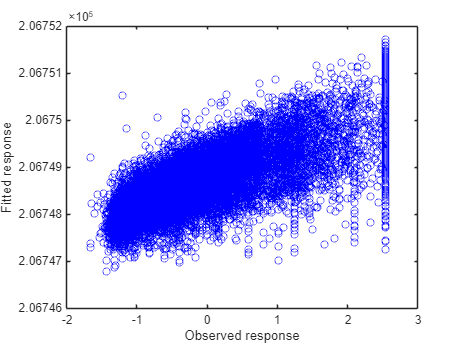

% First six PC's plotted out
figure;
plot(z_Y_calibration,yfit_PCR_calibration, 'bo');
xlabel('Observed response');
ylabel('Fitted response');

% PCR Redo with MSE
MSE_PCR_1 = zeros(9,1);

% Run and plot out MSE change over time
for k = 1:8
    % PCA on current component count
    [coeff_train, score_train] = pca(z_X_calibration);
    % First K components
    X_train_pca = score_train(:, 1:k); 
    
    % Regression fitting with the component size that we on the loop
    beta_PCR_1 = regress(z_Y_calibration, [ones(size(X_train_pca, 1), 1) X_train_pca]);
    
    % PCA -> the test data set being used
    X_test_pca = (X_test_standardized * coeff_train(:, 1:k));
    
    % Fit to predict
    Y_pred_PCR = [ones(size(X_test_pca, 1), 1) X_test_pca] * beta_PCR_1;
    
    % Run mse compute  and store to var
    MSE_PCR_1(k) = mean((Y_test_standardized - Y_pred_PCR).^2);  
end

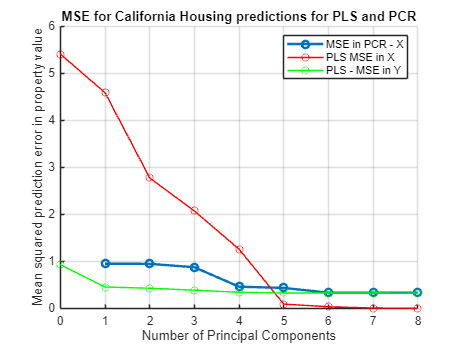

% Plot MSE for PCR and PLS in one plot to see crossing paths
    
figure;
hold on;
plot(1:8, MSE_PCR_1(1:8), '-o', 'LineWidth', 2, 'DisplayName','MSE in PCR - X');
plot(0:8,MSE(1,:),'r-o','DisplayName','PLS MSE in X');
plot(0:8,MSE(2,:),'g-o', 'DisplayName','PLS - MSE in Y');
xlabel('Number of Principal Components');
ylabel('Mean squared prediction error in property value');
title('MSE for California Housing predictions for PLS and PCR');
legend show;
hold off;
grid on;

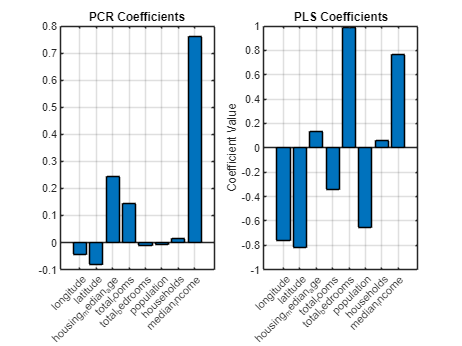

% Task 6 Barplots
coeffs_PCR = beta_PCR(2:end); % Exclude the intercept

% Coefficients for PLS
coeffs_PLS = BETA(2:end); % Exclude the intercept

figure;
subplot(1, 2, 1);
bar(coeffs_PCR);
title('PCR Coefficients');
xticklabels(X_headers);
xtickangle(45);
grid on;

% PLS values
subplot(1, 2, 2); 
bar(coeffs_PLS);
title('PLS Coefficients');
xticklabels(X_headers);
xtickangle(45);
ylabel('Coefficient Value');
grid on;

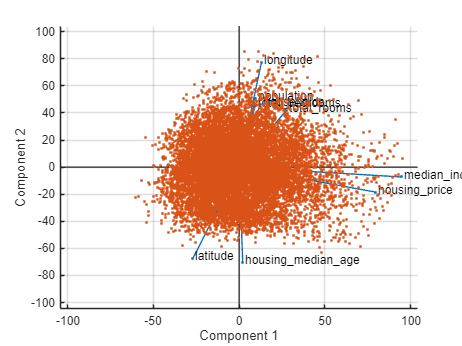

% PLS Triplot - 7 triplot

W = XL;
%W = stats.W;
%disp(size(W,1));
Q = YL;
%disp(size(Q,1));
T = XS;

coefs = [W;Q];

Y_headers = {'housing_price'};

labels = [X_headers, Y_headers];

figure;
biplot(coefs(:,1:2),'Scores',T(:,1:2),'VarLabels',labels);


%textHandles = findobj(b, 'Type', 'text');  % Find all text objects in the biplot
%set(textHandles(end), 'Color', 'r', 'LineWidth', 2);  % Change the color to red and make it thicker

% Task 8 
% Columns to use should be total bedrooms, median income, median age,
% population

% PLS Model
vars_array = [3,5,6,7,8];
vars_amount = 5 + 1;
new_vars = z_X_calibration(:,vars_array);
new_test = X_test_standardized(:,vars_array);

% Five output components from analysis selected as the desired amount
[XL_1,YL_1,XS_1,YS_1,BETA_1,PCTVAR_1,MSE_1,stats_1]= plsregress(new_vars, z_Y_calibration, 5,'cv',5);
disp(MSE_1);

    3.0165    2.3108    1.4600    0.5365    0.0038    0.0000
    0.9271    0.4558    0.4412    0.4251    0.4044    0.4039



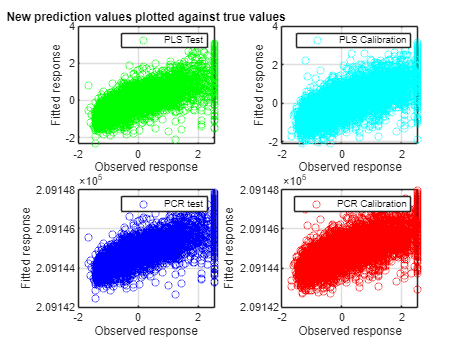


% PLS_v2 MSE Plot
figure;

subplot(2,1,1)
hold on;
plot(1:vars_amount,MSE_1(1,:) ,'b-o', 'DisplayName','MSE in X');
plot(1:vars_amount,MSE_1(2,:), 'r-o', 'DisplayName','MSE in Y');
xlabel('Number of Principal Components for only selected variables');
ylabel('MSE');
title('MSE for California Housing predictions for PLS using selected variables');
grid on;
legend show;
hold off;
subplot(2,1,2)
hold on;
plot(0:8,MSE(1,:) ,'b-o', 'DisplayName','MSE in X');
plot(0:8,MSE(2,:), 'r-o', 'DisplayName','MSE in Y');
xlabel('Number of Principal Components');
ylabel('MSE');
title('Original MSE for PLS using all variables available');
legend show;
grid on;
hold off;
hold off;

%disp(XL);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

Q-squared for the new PLS: 0.63327


Good prediction


% PCR Redo with MSE
MSE_PCR_2 = zeros(5,1);


% Run and plot out MSE change over time
for k = 1:5
    % PCA on current component count
    [coeff_train_2, score_train_2] = pca(new_vars);
    % First K components
    X_train_pca_2 = score_train_2(:, 1:k); 
    
    % Regression fitting with the component size that we on the loop
    beta_PCR_2 = regress(z_Y_calibration, [ones(size(X_train_pca_2, 1), 1) X_train_pca_2]);
    
    % PCA -> the test data set being used
    X_test_pca_2 = (new_test * coeff_train_2(:, 1:k));
    
    % Fit to predict
    Y_pred_PCR_2 = [ones(size(X_test_pca_2, 1), 1) X_test_pca_2] * beta_PCR_2;
    
    % Run mse compute  and store to var
    MSE_PCR_2(k) = mean((Y_test_standardized - Y_pred_PCR_2).^2);  
end


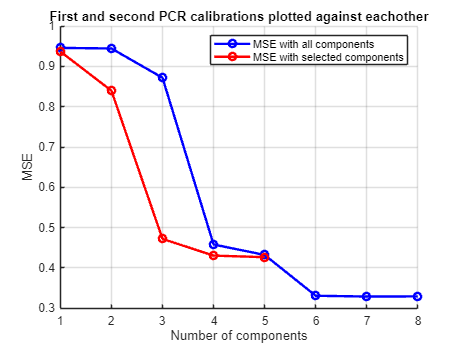

figure;
hold on;
plot(1:8, MSE_PCR_1(1:8), 'b-o', 'LineWidth', 2, 'DisplayName','MSE with all components');
plot(MSE_PCR_2, 'r-o', 'LineWidth', 2, 'DisplayName','MSE with selected components');
xlabel('Number of components')
ylabel('MSE');
title('First and second PCR calibrations plotted against eachother');
grid on;
hold off;
legend show;


%Add first columns of ones
[new_coeff, new_score] = pca(new_vars);

% PCR model + with calibration data
beta_PCR_new = regress(z_Y_calibration, new_score);

beta_PCR_new = new_coeff*beta_PCR_new;

beta_PCR_new = [Y_calibration_mean - X_calibration_mean(:,[3,4,5,7,8])*beta_PCR_new; beta_PCR_new];

% Test data with PCR
yfit_PCR_calibration_new = [ones(size(new_vars,1),1) new_vars]*beta_PCR_new;

yfit_PCR_test_new = [ones(size(X_test_standardized(:,[3,4,5,7,8]),1),1) X_test_standardized(:,[3,4,5,7,8])]*beta_PCR_new;


% Do the same with the PLS new beta
yfit_PLS_calibration_1 = [ones(size(new_vars,1),1) new_vars]*BETA_1;

yfit_PLS_test_1 = [ones(size(X_test_standardized(:,vars_array),1),1) X_test_standardized(:,[3,4,5,7,8])]*BETA_1;

% Q2 work for PLS  second fit
% Leads to worse performance according to the Q2 value
Y_pred = yfit_PLS_calibration_1;
Y_true = z_Y_calibration;
Q2_redo = 1 - sum((Y_true - Y_pred).^2) / sum((Y_true - mean(Y_true)).^2);
disp(['Q-squared for the new PLS: ', num2str(Q2_redo)]);

Q-squared for the new PLS: 0.56481


if Q2_redo > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Good prediction


% Q2 work for PLS  second fit
% Leads to worse performance according to the Q2 value
Y_pred = yfit_PLS_test_1;
Y_true = Y_test_standardized;
Q2_redo_test = 1 - sum((Y_true - Y_pred).^2) / sum((Y_true - mean(Y_true)).^2);
disp(['Q-squared for the new PLS: ', num2str(Q2_redo_test)]);

Q-squared for the new PLS: 0.41278


if Q2_redo_test > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Not good prediction



disp(Q2_in_test - Q2_redo_test)

    0.2429



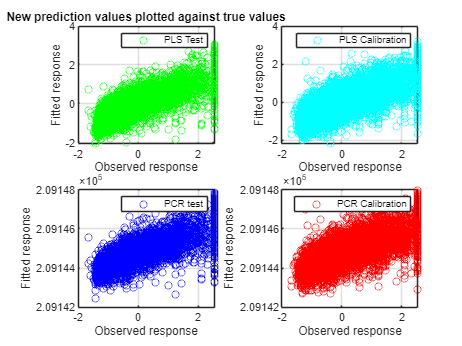

% Predicted values against true values
figure;
hold on;
% PLS Test
subplot(2,2,1)
plot(Y_test_standardized, yfit_PLS_test_1, 'go', 'DisplayName','PLS Test');
legend show;
title('New prediction values plotted against true values');
xlabel('Observed response');
ylabel('Fitted response');
% PLS calibration
grid on;
subplot(2,2,2)
plot(z_Y_calibration, yfit_PLS_calibration_1, 'co', 'DisplayName','PLS Calibration');
legend show;
xlabel('Observed response');
ylabel('Fitted response');
grid on;

% PCR test
subplot(2,2,3)
plot(Y_test_standardized, yfit_PCR_test_new, 'bo', 'DisplayName','PCR test');
legend show;
xlabel('Observed response');
ylabel('Fitted response');
% PCR calibration
grid on;
subplot(2,2,4)
plot(z_Y_calibration, yfit_PCR_calibration_new, 'ro', 'DisplayName','PCR Calibration');
grid on;
legend show;
xlabel('Observed response');
ylabel('Fitted response');


hold off;

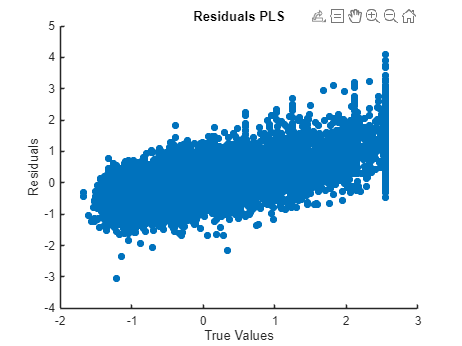

% 10

% Residuals PLS
%resids = z_Y_calibration - stats_1.Yresiduals;
figure;
scatter(z_Y_calibration, stats_1.Yresiduals, 'filled','DisplayName','PLS Calibration');
title('Residuals PLS');
xlabel('True Values');
ylabel('Residuals');

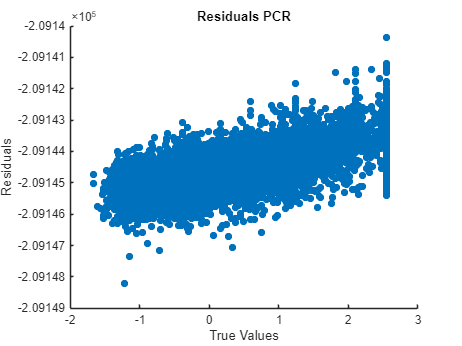


% Residuals PCR
figure;
resids_PCR = z_Y_calibration - yfit_PCR_calibration_new;
scatter(z_Y_calibration, resids_PCR, 'filled','DisplayName','PCR Calibration');
xlabel('True Values');
ylabel('Residuals');
title('Residuals PCR');